clear all; close all; clc;

In the following exercise, you will use a Fourier transform to find the frequency components of a signal buried in noise. Specify the parameters of a signal with a sampling frequency of 1 kHz and a signal duration of 1.5 seconds.

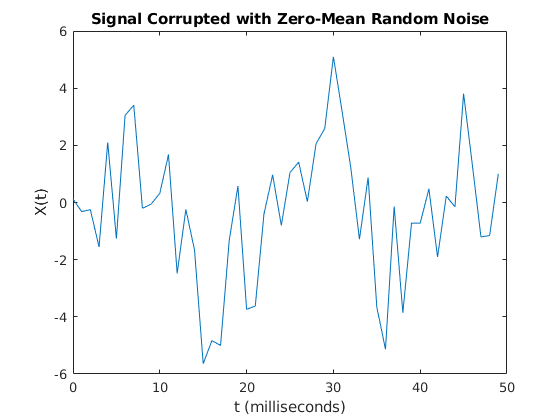

Fs = 1000;            % Sampling frequency                    
T = 1/Fs;             % Sampling period       
L = 1500;             % Length of signal seconds
t = (0:L-1)*T;        % Time vector

% TODO: Form a signal containing a 77 Hz sinusoid of amplitude 0.7 and a 43Hz sinusoid of amplitude 2.
A_1 = 0.7;               % Amplitude
f_1 = 77;                % Frequency

A_2 = 2;                 % Amplitude
f_2 = 43;                % Frequency

S = A_1*sin(2*pi*f_1*t) + A_2*sin(2*pi*f_2*t);

% Corrupt the signal with noise 
X = S + 2*randn(size(t));

% Plot the noisy signal in the time domain. It is difficult to identify the frequency components by looking at the signal X(t). 
plot(1000*t(1:50) ,X(1:50))
title('Signal Corrupted with Zero-Mean Random Noise')
xlabel('t (milliseconds)')
ylabel('X(t)')

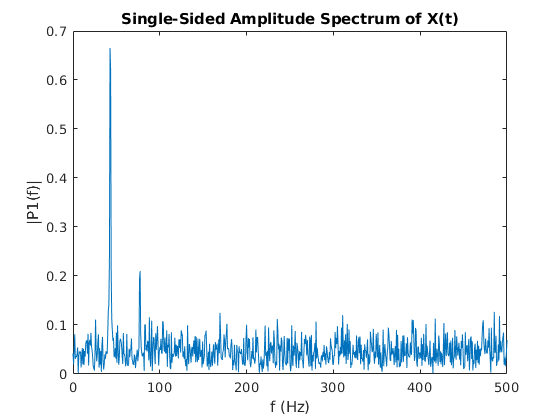


% TODO : Compute the Fourier transform of the signal. 
Y = fft(X);
P2 = abs(Y/L);

% TODO : Compute the two-sided spectrum P2. Then compute the single-sided spectrum P1 based on P2 and the even-valued signal length L.
P1 = P2(1:L/2+1);

% Plotting
f = Fs*(0:(L/2))/L;
plot(f,P1) 
title('Single-Sided Amplitude Spectrum of X(t)')
xlabel('f (Hz)')
ylabel('|P1(f)|')  